#                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              MAIN CODE FILE

- Documentation paragraph that describes what your main code does, in enough detail that a cogent fellow programmer can follow it.

This code controls a wheeled autonomous rover performing a series of three outdoor missions around the Olin Oval. The missions are:

- Waypoint Navigation

- Docking

- Scientific Payload Delivery

This program will prompt the user for a mission number and enter the robot control loop and run the behaviour engine specific to that mission. To find its way around the oval, the rover takes desired location waypoints as inputs. To navigate around potential obstacles in an outdoor environment, the rover has a sensory suite that adds data to a rover-centric occupancy grid. From this grid, a weighted vector (brainwave) is produced that minimizes the potential for collision. Other mission-specific tasks use this concept of brainwave arbitration to determine which steering angle is the best to take.

- Wiring diagram of your robot

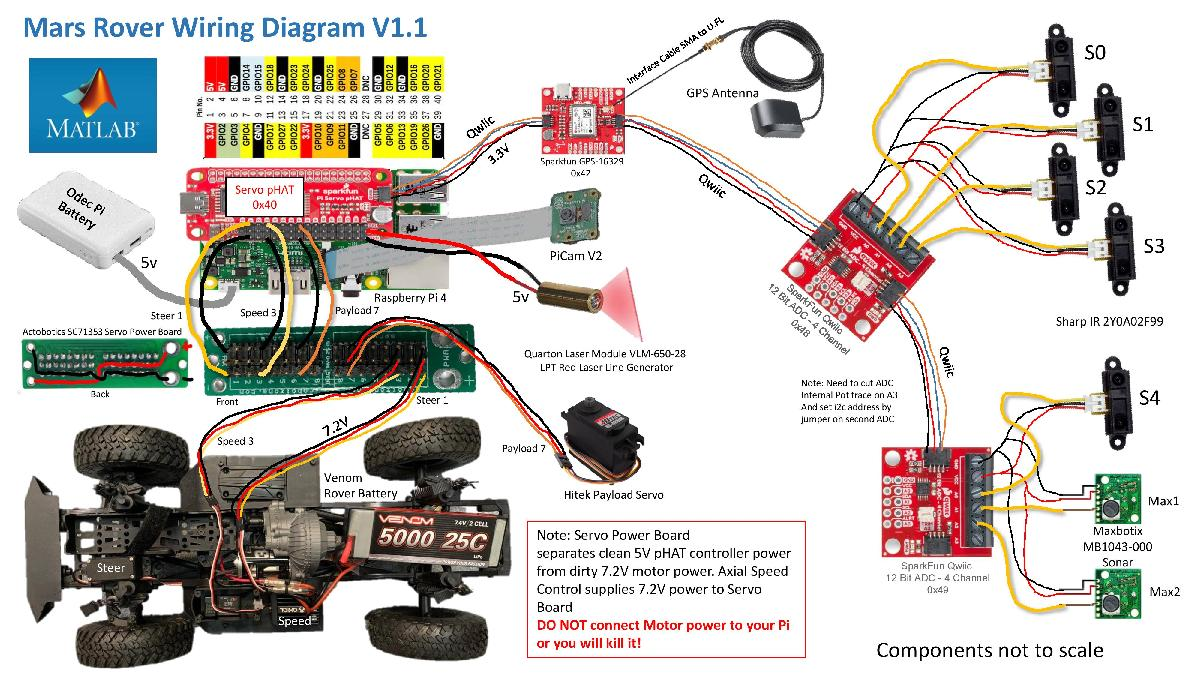

- Clear indication of what external Matlab code parts

The program OlinRoverSetup is used to set up the rover’s Raspberry Pi, sensing and actuation hardware, and create global variables. It's also where mission parameters and data, such as waypoints and the main occupancy grid, are set up.

clc                     % clear command window
clear    
clf reset% clear MATLAB workspace
% profile on            % profile used to time each segment of code
disp('note: It takes a 10 seconds or so to download code to Raspberry PI '); 

note: It takes a 10 seconds or so to download code to Raspberry PI 


[robotPi, blinkLED]= RaspPiSetup()

robotPi =   raspi with properties:

         DeviceAddress: '192.168.34.15'               
                  Port: 18734                         
             BoardName: 'Raspberry Pi Model B+'       
         AvailableLEDs: {'led0'}                      
  AvailableDigitalPins: [4,5,6,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27]
  AvailableSPIChannels: {'CE0','CE1'}                 
     AvailableI2CBuses: {'i2c-1'}                     
      AvailableWebcams: {'bcm2835-isp (platform:bcm2835-isp)','mmal service 16.1 (platform:bcm2835-v4l2)'}
           I2CBusSpeed: 100000                        

  Supported peripherals


blinkLED = 'led0'


% Turn on board LED on and off to signal program has started 
%Blink(robotPi,blinkLED,10);
disp('Warning! Robot Rover Active! ');

Warning! Robot Rover Active! 



% Set up servos, PiCam, and QWIIC analog input
[roverServos] = ServoSetup(robotPi)

ans = 1×5 cell array
    {'0x40'}    {'0x42'}    {'0x48'}    {'0x49'}    {'0x70'}


roverServos =   I2C_Servo_pHAT with properties:

                DEFAULT_I2C_BUS: 'i2c-1'
             DEFAULT_HW_ADDRESS: '0x40'
                   DEFAULT_NAME: "Pi Servo HAT"
        DEFAULT_SERVO_FREQUENCY: 50
    DEFAULT_SERVO_MAX_DUTYCYCLE: 0.5000
    DEFAULT_SERVO_MIN_DUTYCYCLE: 0.0750
         DEFAULT_SERVO_OP_ANGLE: 190
                         gcAddr: '0x00'
                         acAddr: '0x70'
                      subAddr_1: '0x71'
                      subAddr_2: '0x72'
                      subAddr_3: '0x74'
                         device: [1×1 raspi.internal.I2Cdev2]
                      servoAddr: [1×16 struct]
            SERVO_MAX_DUTYCYCLE: 0.5000
            SERVO_MIN_DUTYCYCLE: 0.0750
                 SERVO_OP_ANGLE: 190
                SERVO_FREQUENCY: 50


% [robotCam] = PiCamSetup(robotPi)
[adcDevice1, adcDevice2] = QWIICInputSetup(robotPi)

rawRangeData1 =     1.0602    0.9638    0.2891    0.6104


rawRangeData2 =     0.0344    0.4178    0.7710    2.8590


adcDevice1 =   ads1015 with properties:

             Address: 72
       OperatingMode: 'continuous'
        VoltageScale: 4.0960
    SamplesPerSecond: 3300


adcDevice2 =   ads1015 with properties:

             Address: 73
       OperatingMode: 'continuous'
        VoltageScale: 4.0960
    SamplesPerSecond: 3300


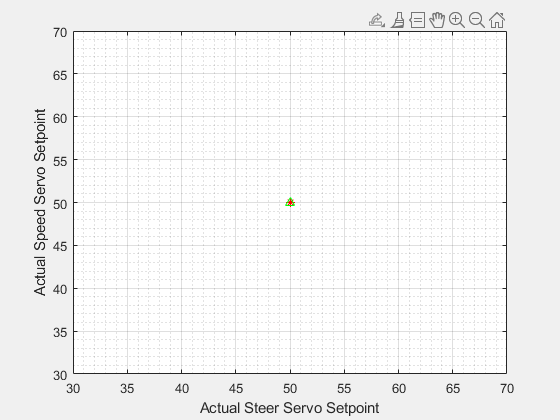

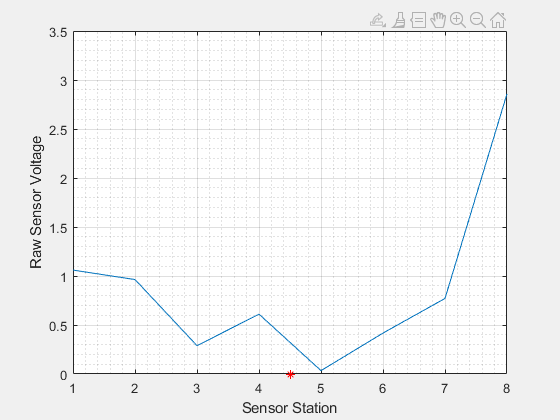

neo =   NEO_M8U with properties:

       DEFAULT_I2C_BUS: 'i2c-1'
    DEFAULT_HW_ADDRESS: '0x42'
          DEFAULT_NAME: "I2C_NEO_M8U"
                   ubx: [1×1 UBX]
                device: [1×1 raspi.internal.I2Cdev2]
                  data: []


[neo] = GPSSetup(robotPi)

% [roverJoy] = JoystickSetup(1)

**INITIALIZE ROVER OCCUPANCY GRID**

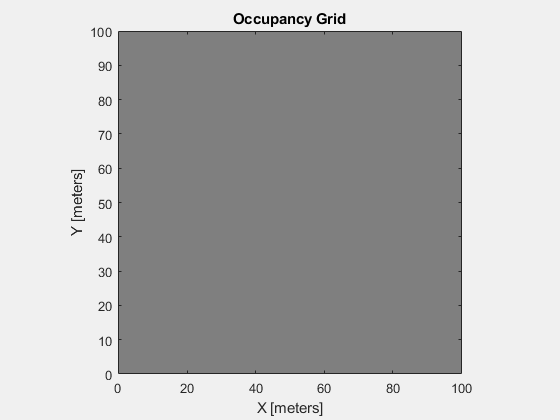

% Create an empty map of the same dimensions as the test track map                      
roverOccupancyGrid = occupancyMap(100,100);  % Make empty map the same size
% Create free floating figure (Rover occupancy grid)
figureRoverOccupancy = figure('name', 'RoverOccupancyGrid', 'NumberTitle', 'off', 'Visible', 'on');
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);         % Show the map in figure window

**Plotting Waypoints Onto Occupancy Grid**

%     load waypoints.mat
%     p = 0.7;
%     for i = 1:length(waypoints)
%         [gridIndex] = GPSCoordToGridIndex(waypoints(i,:),waypoints);
%         updateOccupancy(roverOccupancyGrid,[gridIndex(1) gridIndex(2)],p);
%     end


% Create free floating figure (Arbiter)
% figureArbiter = figure('name', 'BrainWavesArbitor', 'NumberTitle', 'off', 'Visible', 'on');
% figure(figureArbiter);                            
%     pbrain = plot([-35:35], zeros(71,1));
%     axis([-35 35 -5 5]);
%     grid on;
%     grid minor;

**CREATE GLOBAL VARIABLES**

sampleTime = 0.5;                                  % Sample time [s]
t = 0:sampleTime:100;                              % Time array
r = rateControl(1/sampleTime);                     % reset control loop  rate
reset(r);                                          % reset loop time to zero
GPSToGridRatio = 2; % CHANGE THIS

**CREATE MISSION DEFINITION FILE**

% % Create index for MDF table
% WayPoint = (0:1:4);                                        
% WayPoint = WayPoint';
% 
% % Create inital target waypoints
% xLongitude = [ -71.227875 ; -71.227875 ;-71.227875 ;-71.227875 ;-71.227875];
% yLatitude = [ 42.276295 ; 42.276295 ;42.276295 ;42.276295 ;42.276295];
% 
% % Build list of desired behaviors for Mission 1
% BehaviorOne = ['Forward_____' ; 'purePursuit_'; 'purePursuit_'; 'pursuitAvoid' ; 'pursuitAvoid'];
% MDFOne = table(WayPoint,xLongitude,yLatitude,Behavior)      % Build Mission Definition File (MDF) table
%  
% % Build list of desired behaviors for Mission 2
% BehaviorTwo = ['Forward_____' ; 'purePursuit_'; 'purePursuit_'; 'pursuitAvoid' ; 'pursuitAvoid'];
% MDFTwo = table(WayPoint,xLongitude,yLatitude,Behavior)      % Build MDF table
% 
% % Build list of desired behaviors for Mission 2
% BehaviorThree = ['Forward_____' ; 'purePursuit_'; 'purePursuit_'; 'pursuitAvoid' ; 'pursuitAvoid'];
% MDFThree = table(WayPoint,xLongitude,yLatitude,Behavior)      % Build MDF table

**ASK FOR MISSION NUMBER**

% mission_number = input('Enter mission number: ');

**READY TO RUN ROBOT?**

% userInput = questdlg('Ready to run Rover?', 'Start Mission');

## Run Robot Control Loop

                   % set drivespeed to zero
    controlFlag = 1;                     % create a loop control

  % Get Current Location
    roverLocation = [42.2932328400000	-71.2642964400000];
     roverBearing = 0;
%      [roverOccupancyGrid, roverBearing, roverLocation, gate_number] = GPSGetLocation(roverOccupancyGrid,neo)
     %GET IR AND SONAR DATA
     while 1  
         [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid,roverBearing, roverLocation, adcDevice1, adcDevice2)
          roverLocation = roverLocation + 0.0000001;
          roverBearing = roverBearing + .1;
          figure(figureRoverOccupancy);                            
           show(roverOccupancyGrid); 
     end

posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8887   16.4666


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    22.7147   16.7847


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8363   16.4753


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.0470   16.8665


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.7922   16.4826


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8386   16.4755


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    22.7631   16.7738


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8810   16.4865


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.0577   16.8769


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8023   16.4926


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8312   16.4852


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    22.7435   16.8022


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8563   16.4953


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.0684   16.8874


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8123   16.5026


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8499   16.4954


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    22.7013   16.8440


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8663   16.5053


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.0791   16.8977


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8222   16.5126


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    24.0860   16.5093


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    22.7796   16.8154


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8763   16.5153


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.0941   16.9006


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8323   16.5226


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    24.0960   16.5193


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    22.8124   16.8132


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8950   16.5256


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.1006   16.9186


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8423   16.5326


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.9840   16.5272


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    22.7707   16.8551


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8963   16.5353


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.1113   16.9290


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8523   16.5426


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8978   16.5355


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    22.7663   16.8749


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.9150   16.5456


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.1263   16.9318


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8622   16.5526


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    24.1260   16.5493


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    22.7996   16.8725


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.9249   16.5556


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.1327   16.9498


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8635   16.5622


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.9876   16.5567


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    22.8025   16.8881


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.9350   16.5656


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.1519   16.9450


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex =    23.8735   16.5722


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9278   16.5655


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.8131   16.8990


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9449   16.5756


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1584   16.9630


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.8923   16.5826


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1555   16.5793


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.8237   16.9100


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9463   16.5853


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1649   16.9810


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9023   16.5926


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0700   16.5876


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.8568   16.9074


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9650   16.5956


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1756   16.9914


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9123   16.6026


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0100   16.5964


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.8374   16.9366


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9663   16.6053


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1864   17.0018


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9222   16.6126


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0374   16.6067


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.8406   16.9521


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9937   16.6159


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2012   17.0046


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9149   16.6217


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0476   16.6167


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.8735   16.9495


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9863   16.6253


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2078   17.0226


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9423   16.6326


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2060   16.6293


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.8396   16.9879


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0137   16.6359


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2227   17.0253


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9522   16.6426


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9986   16.6355


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.9168   16.9578


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0063   16.6453


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2293   17.0434


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9535   16.6522


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0260   16.6458


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.8240   17.0328


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0163   16.6553


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2400   17.0537


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9636   16.6622


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0795   16.6566


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.8493   17.0349


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0437   16.6659


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2507   17.0642


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9736   16.6722


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1063   16.6669


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.9858   16.9673


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0450   16.6756


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2655   17.0668


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.9835   16.6822


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0901   16.6764


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.9298   17.0199


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0463   16.6853


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2763   17.0772


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0023   16.6926


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2660   16.6893


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.9553   17.0215


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0563   16.6953


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2870   17.0876


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.6984   16.6862


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0578   16.6955


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.9953   17.0139


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0665   16.7053


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2937   17.1057


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0223   16.7126


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2860   16.7093


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.0206   17.0155


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0763   16.7153


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3044   17.1161


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0322   16.7226


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2960   16.7193


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.9796   17.0592


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0863   16.7253


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3191   17.1188


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0422   16.7326


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1140   16.7259


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.9461   17.0984


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1049   16.7356


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3259   17.1368


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0610   16.7431


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0978   16.7355


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   22.9715   17.1000


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1063   16.7453


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3406   17.1395


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0623   16.7526


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3253   16.7493


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.0261   17.0826


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1250   16.7556


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3473   17.1576


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0723   16.7626


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1178   16.7555


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.0441   17.0888


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1263   16.7653


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3620   17.1603


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.0823   16.7726


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1889   16.7666


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.0181   17.1235


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1885   16.7771


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3688   17.1784


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1009   16.7831


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3553   16.7793


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.0726   17.1059


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1636   16.7859


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3795   17.1888


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1023   16.7926


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3310   16.7887


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.0905   17.1120


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1563   16.7953


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3942   17.1913


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1123   16.8026


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2625   16.7973


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.0938   17.1277


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1749   16.8056


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4049   17.2017


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1135   16.8122


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1678   16.8055


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1116   17.1338


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1850   16.8156


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4196   17.2043


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1323   16.8226


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3960   16.8193


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1368   17.1351


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1863   16.8253


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4225   17.2302


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1423   16.8326


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4060   16.8293


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.0747   17.1943


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1963   16.8353


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4410   17.2250


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1523   16.8426


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2414   16.8363


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.0636   17.2198


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2063   16.8453


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4478   17.2431


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1536   16.8522


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3036   16.8472


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.0815   17.2259


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2163   16.8553


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4624   17.2457


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1722   16.8626


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2789   16.8566


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1501   17.1981


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2263   16.8653


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4693   17.2639


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1822   16.8726


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2714   16.8663


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1679   17.2041


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2450   16.8756


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4838   17.2664


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1923   16.8826


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2291   16.8753


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.0846   17.2786


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2463   16.8853


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4946   17.2767


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.1935   16.8922


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3176   16.8867


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1387   17.2602


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2737   16.8959


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5015   17.2950


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2123   16.9026


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3276   16.8967


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1854   17.2466


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2663   16.9053


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5084   17.3132


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2223   16.9126


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3027   16.9061


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1600   17.2822


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2763   16.9153


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5267   17.3078


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2323   16.9226


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4953   16.9193


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1779   17.2882


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2863   16.9253


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5374   17.3181


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2423   16.9326


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3576   16.9267


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2316   17.2695


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3224   16.9362


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5407   17.3442


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2523   16.9426


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3152   16.9358


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2208   17.2952


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3063   16.9453


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5514   17.3545


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2623   16.9526


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3514   16.9463


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.1884   17.3361


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3163   16.9553


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5659   17.3570


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2723   16.9626


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5360   16.9593


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2206   17.3321


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3263   16.9653


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5766   17.3674


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2910   16.9731


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3365   16.9656


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2598   17.3231


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3275   16.9750


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5837   17.3856


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.2923   16.9826


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3552   16.9758


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2348   17.3590


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3463   16.9853


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5944   17.3960


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3023   16.9926


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5660   16.9893


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2452   17.3702


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3563   16.9953


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.6125   17.3905


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3123   17.0026


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5760   16.9993


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2775   17.3658


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3575   17.0050


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.6159   17.4167


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3223   17.0126


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5852   17.0093


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3238   17.3515


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3675   17.0150


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.6303   17.4191


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3323   17.0226


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3952   17.0158


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2420   17.4282


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3949   17.0256


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.6374   17.4374


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3422   17.0326


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.6060   17.0293


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3379   17.3783


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3963   17.0353


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.6482   17.4477


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3523   17.0426


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.6160   17.0393


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.2564   17.4554


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4150   17.0456


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.6589   17.4580


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3623   17.0526


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4775   17.0467


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3238   17.4256


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4163   17.0553


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.6733   17.4604


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3723   17.0626


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4178   17.0555


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3062   17.4570


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4263   17.0653


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.6804   17.4787


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3823   17.0726


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4801   17.0664


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3734   17.4270


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4363   17.0753


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.6947   17.4811


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3923   17.0826


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5076   17.0767


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3488   17.4636


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4550   17.0856


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.7019   17.4994


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4023   17.0926


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5176   17.0867


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4088   17.4384


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4650   17.0956


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.7162   17.5017


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.3948   17.1017


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.6760   17.0993


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4264   17.4441


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4663   17.1053


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.7235   17.5200


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4135   17.1122


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5289   17.1066


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4090   17.4757


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5024   17.1162


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.7377   17.5224


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4323   17.1226


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.6610   17.1187


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4477   17.4658


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4863   17.1253


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.7554   17.5167


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4423   17.1326


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5140   17.1259


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.3883   17.5287


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4963   17.1353


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.7557   17.5510


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4522   17.1426


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5065   17.1356


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4899   17.4719


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5150   17.1456


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.7734   17.5454


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4623   17.1526


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.6300   17.1476


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4726   17.5036


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5250   17.1556


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.7841   17.5557


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4723   17.1626


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5527   17.1561


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4553   17.5354


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5437   17.1659


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.7880   17.5820


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4735   17.1722


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.7460   17.1693


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4242   17.5779


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5363   17.1753


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.8022   17.5843


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4836   17.1822


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5989   17.1766


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4836   17.5520


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5463   17.1853


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.8129   17.5946


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5022   17.1926


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.6176   17.1867


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4943   17.5629


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5563   17.1953


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.8203   17.6130


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5122   17.2026


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5404   17.1952


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5119   17.5685


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5663   17.2053


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.8311   17.6234


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.4874   17.2108


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.6725   17.2073


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.4533   17.6324


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5763   17.2153


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.8418   17.6336


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5235   17.2222


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5952   17.2158


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5125   17.6062


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.6473   17.2274


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.8526   17.6440


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.5335   17.2322


roverOccupancyGrid =   occupancyMap with properties:

             XWorldLimits: [0 100]
             YWorldLimits: [0 100]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1
                 GridSize: [100 100]
             XLocalLimits: [0 100]
             YLocalLimits: [0 100]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   24.6314   17.2263


posX = 42.2932

posY = -71.2643

obstaclePosX = 42.2932

obstaclePosY = -71.2643

gridIndex = 1×2
   23.5095   17.6276



% Some initial code to get out of the dock
waypoint = 1;
load('waypoints.mat');
switch mission_number
    case 1 % Mission 1: Driving at obstacle avoidance
        while true
            % Get Current Location
            [roverOccupancyGrid, roverBearing, roverLocation, gate_number] = GPSGetLocation(roverOccupancyGrid,neo)
            % Pantilt and Sense
            [roverOccupancyGrid] = MissionOneSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1,adcDevice2, robotCam)
            % Find target waypoint 
%             targetWaypoint = [MDF{waypoint,2} MDF{waypoint,3}];
            targetWaypoint = [waypoints(waypoint,1) waypoints(waypoint,2)];      % new waypoints
            % Find angle for the next waypoint and turning in that
            % direction
            bearing = GoToWayPoint(roverOccupancyGrid,targetWaypoint);
            DriveRover(robotPi,roverServos,bearing, 0);
            % Find behaviour to execute
            roverBehavior = MDF{WPn,4};
            % Find distance between rover and target waypoint
            distToTarget = norm(roverLocation-targetWaypoint);
            
            % If rover is not at the target gate, repeat WP loop
            while deg2km(distToTarget)/1000 > 5
                tic
                while toc < 3
                    % Execute think behaviour( also think about what do to for cases
                    % where there is more than one behaviour to execute)
                    [steerRef] = ExecuteThinkBehaviour(roverBehavior);
                    DriveRover(robotPi,roverServos,steerRef,61) % act on the given steering angle
                end
                DriveRover(robotPi,roverServos,steerRef,0)   % stop rover
                pause(1)
                % Update rover location and distance to target waypoint
                [roverOccupancyGrid, roverBearing, roverLocation] = GPSGetLocation(roverOccupancyGrid, neo)
                distToTarget = norm(roverLocation-targetWaypoint);   % update distance to target
            end
            waypoint = waypoint + 1;
            if waypoint == 7     % If rover has reached last waypoint
                break
            end
        end
    
    
    case 2 % mission 2: docking
    
    
    case 3 % mission 3: payload
        
end

## Clean shut down

Put all actualtors into a safe position, release all control objects and shut down all communication paths.

% Stop program and clean up the connection to Pi
% when no longer needed 
  roverServos.setServoPWM(1,50);       % Center steering Wheels
  roverServos.setServoPWM(3,50);       % Turn Drive Motor off
  % close all;                           % clear data figure plots
  clc                                  % clear commad window
  clear robotPi                        % clear Pi object
  beep              % play system sound to let user know program is ended
  

Check quasi real-time loop performance (Dave and Matlab working on ways to speed this up)

  disp(r);
  stats = statistics(r)                % check real-time loop execution time stats
  disp('Rover Test program has ended');
  disp('Dont forget to shut down Pi cleanly before you power it off');

*At end of each programming session, please don't forget to shutdown your Pi cleanly by using the follwing at the command line:*

## `h = robotPi`

## `h.execute('sudo shutdown -h now')`

  % leave next line commented out
  %  profile viewer                    % view code runtimes graphically

## Robot Functions(store the local functions here)

**SENSE FUNCTIONS**

function[roverOccupancyGrid, roverBearing, roverLocation, gate_number] = GPSGetLocation(roverOccupancyGrid,neo) % this will be provided from canvas
basic_data = neo.getBasic();
% roverX = basic_data.longitude
% roverY = basic_data.lattitude
roverLocation = [basic_data.longitude basic_data.lattitude];
roverBearing = basic_data.heading;
% add code for making the gate number thing work
gate_number = 1;
% plotting rover position on occupancy grid through conversion
[gridIndex] = GPSCoordToGridIndex(GPSCoordinate);
pvalues = 0.6; % this is the value for the rover position
updateOccupancy(roverOccupancyGrid,[gridIndex(1) gridIndex(2)],pvalues);
end

% function [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, roverBearing, roverLocation, adcDevice1, adcDevice2)
function [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid,roverBearing, roverLocation, adcDevice1, adcDevice2)
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData2(1:3),rawRangeData1(1:2)]; 
     angles = [1 2 3 4 5; -60+roverBearing -30+roverBearing 0+roverBearing 30+roverBearing 60+roverBearing]; % chagne this later     
     threshold = 40;
     %convert to lat/long
      threshold = 40/1100000;
     for i = 1:5
        % voltage to distance     
        distance = (rawRangeData(i) - 2.805)/(-0.03316);
        distance = distance/11100000;
        if distance < threshold
            [obstaclePosX, obstaclePosY] = findGridPos(angles(i), distance, roverLocation)
            [gridIndex] = GPSCoordToGridIndex([obstaclePosX obstaclePosY])
            updateOccupancy(roverOccupancyGrid, [gridIndex(1) gridIndex(2)], 0.1)
        end   
     end  
end

function [roverOccupancyGrid] =  SharpSONARRange(roverOccupancyGrid,roverBearing, roverLocation, adcDevice1, adcDevice2)
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData1(3:4)]; 
     angles = [1 2; -90+roverBearing 90+roverBearing]; % chagne this later     
     threshold = 60;
     %convert to lat/long
      threshold = 40/1100000;
     for i = 1:2
        % voltage to distance     
        distance = (rawRangeData(i,:) - 0.01063)/(0.01584);
       distance = distance /11100000;
        if distance < threshold
            [obstaclePosX, obstaclePosY] = findGridPos(angles(i), distance, roverLocation);
            [gridIndex] = GPSCoordToGridIndex([obstaclePosX obstaclePosY]);
            updateOccupancy(roverOccupancyGrid, [gridIndex(1) gridIndex(2)], 0.1)
        end   
     end  
end

function[roverOccupancyGrid] = PiCamLaser(roverOccupancyGrid, roverBearing, roverLocation, robotCam) % laser for obstacle avoidance
% Mark obstacles on the grid
end

function[roverOccupancyGrid] = PiCamObstacles(roverOccupancyGrid, roverBearing, roverLocation, robotCam) % color masking for obstacles
% Mark obstacles on the grid
end

function [roverOccupancyGrid] = SonarRange(roverOccupancyGrid, figureRoverOccupancy, headBearing, roverLocation, adcDevice1) % fill in other variables
% Mark obstacles based on the positions on the grid

    % Sonar calibration, covert voltage data into distance measurement (cm)
    distanceLeft = (rawRangeData(1, 1)-0.01063)/0.01584; 
    distanceRight = (rawRangeData(2, 1)-0.01063)/0.01584;
    
    % If measured distance is within some threshold, mark it as an obstacle
    % on the occupancy grid
    threshold = 5;
    if distanceLeft < threshold
        omegaLeft = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaLeft, distanceLeft, roverLocation);
        [gridIndex] = GPSCoordToGridIndex([obstaclePosX obstaclePosY]);
        updateOccupancy(roverOccupancyGrid, [gridIndex(1) gridIndex(2)], 0.1)
        
    end
    if distanceRight < threshold 
        omegaRight = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaRight, distanceRight, roverLocation);
        [gridIndex] = GPSCoordToGridIndex([obstaclePosX obstaclePosY]);
        updateOccupancy(roverOccupancyGrid, [gridIndex(1) gridIndex(2)], 0.1);
    end
end

function[roverOccupancyGrid]  =  PiCamDockFind(roverOccupancyGrid, panAngle, tiltAngle) 
% Find the location of the red dot, and mark it on the grid
end

function[roverOccupancyGrid]  =  PiCamAprilTagFind(roverOccupancyGrid,panAngle, tiltAngle) %why is there pan and tilt angle
% Find the location of the april tags and mark it on the grid
end

function[roverOccupancyGrid] = MissionOneSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1,adcDevice2, robotCam)
%% TODO for sonar function, headBearing == roverBearing + (panAngle converted to global bearing)
    
    joystickControl=1
    while joystickControl == 1
        % Use joystick to move rover head, Y + enter when ready to sense
        while 1
            [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
            DrivePanTilt(panAngle, tiltAngle)
            stop=input('Ready to sense? type Y then hit enter ','s');
            if stop == 'Y'
                break
            end
        end
        % Call all the sense functions related to Mission 1
        [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1, adcDevice2) % fill in other variable
        [roverOccupancyGrid] = PiCamLaser(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % laser for obstacle avoidance
        [roverOccupancyGrid] = PiCamObstacles(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % color masking for obstacles
        [roverOccupancyGrid] =  SonarRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing+panAngle, roverLocation, adcDevice1) % fill in other variables
       
        figure(figureRoverOccupancy);     % Show updated occupancy grid
            hold on;
            show(roverOccupancyGrid);
            grid on;
            grid minor;
            hold off;
        
        joystickControl=input('Keep sensing? (0-1)');
    end
end

function[roverOccupancyGrid] = MissionTwoSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation)
    joystickControl=1
    while joystickControl == 1
        gtest=input('Ready to sense? type Y then hit enter','s');
        [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
        DrivePanTilt(panAngle, tiltAngle)
        [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation) % fill in other variable
        [roverOccupancyGrid] = PiCamLaser(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation) % laser for obstacle avoidance
        [roverOccupancyGrid] = PiCamObstacles(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation) % color masking for obstacles
        [roverOccupancyGrid] =  SonarRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing+panAngle, roverLocation) % fill in other variables
        [roverOccupancyGrid]  =  PiCamAprilTagFind(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation) % look for dock april tag
        [roverOccupancyGrid]  =  PiCamDockFind(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation) % look for dock red dot
        
        figure(figureRoverOccupancy);
            hold on;
            show(roverOccupancyGrid);
            grid on;
            grid minor;
            hold off;
            
        joystickControl=input('Keep controlling joystick? (0-1)');
    end
end

function[roverOccupancyGrid] = MissionThreeSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation)

end

function [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
% this function polls USB joystick and returns x position 
% for Rover steering angle and y position for Rover velocity
    stickX = axis(roverJoy, 1);     % X-axis is joystick axis 1 (-1 to 1)
    stickY = axis(roverJoy, 2);     % Y-axis is joystick axis 2 (-1 to 1)
    panAngle = 50 + (10 * stickX);  % scale X for servo with pulse centered at 50
    tiltAngle = 50 + (-10 * stickY);  % scale Y for servo with pulse centered at 50
end

function rawRangeDataN = SENSE_ADC(adcDeviceN)
     % read ADC1 Pin 0-4 voltage
    rawRangeDataN = [adcDeviceN.readVoltage(0), adcDeviceN.readVoltage(1), ...
                adcDeviceN.readVoltage(2), adcDeviceN.readVoltage(3)]; 
end

**THINK FUNCTIONS**

function [posX, posY] = findGridPos(omega, distance, roverLocation) % Helper function for sonar / IR
    if omega < 0
        omega = 360+omega;
    elseif omega > 360
        omega = omega-360;
    end
    quo = omega/90;
    modulo = mod(omega,90);
    if floor(quo) == 0 % Quadrant I
        posX = roverLocation(1) + (distance*cosd(modulo))
        posY = roverLocation(2) + (distance*sind(modulo))
    elseif floor(quo) == 1 % Quadrant IV
        posX = roverLocation(1) + (distance*cosd(modulo))
        posY = roverLocation(2) - (distance*sind(modulo))
    elseif floor(quo) == 2 % Quadrant III
        posX = roverLocation(1) - (distance*cosd(modulo))
        posY = roverLocation(2) - (distance*sind(modulo))
    elseif floor(quo) == 3 % Quadrant IV
        posX = roverLocation(1) - (distance*cosd(modulo))
        posY = roverLocation(2) + (distance*sind(modulo))
    end
end
    
function [waypointSteeringVector] = GoToWayPoint(roverOccupancyGrid,targetWaypoint, roverBearing, roverLocation)

    % Initialize the waypoint vector
    waypointSteeringVector = zeros(13,1);
    
    % Do math to find radius of bumblebee circle
    xdist = targetWaypoint(1) - roverLocation(1);
    ydist = targetWaypoint(2) - roverLocation(2);
    omega = 360 - roverBearing;
    a = 1-cosd(omega)^2-sind(omega)^2;
    b = 2*(cosd(omega)*xdist + sind(omega)*ydist);
    c = xdist^2 + ydist^2;
    radius = roots(a, b, c);
    
    % Convert radius to a bearing
    n = 1 % steering ratio
    s =  1;% wheel base
    a = (n/2)*acos((2-(s^2/radius^2))/2); % steering angle
    
    
    % finding the index for the turn angles to change
    a = (round(a/30))*30;
    turnAngles = -180:30:180;   % 13 vectors( y range is from -1 to 1)
    ind = find(abs(turnAngles - bearing) <= 0.001);
    
    % Change the steering vector
    waypointSteeringVector(ind) = 0.5;

end

function [avoidSteeringVector] = ObstacleAvoid(roverOccupancyGrid, roverLocation)
turnAngles = -180:30:180;   % 13 vectors( y range is from -1 to 1)
mapMatrix = occupancyMatrix(roverOccupancyGrid);
avoidSteeringVector = zeros(71,1);
threshold_distance = 10; % change this value
% if the obstacles are marked as 0.1, find the index of the points marked
[location(:,1),location(:,2)] = find(abs(mapMatrix - 0.1) <= 0.001);
for i = 1:length(location(1))
    % this should be the coordinates of a single wall point
    obstacle_point = [location(i,1), location(i,2)];
    % finding the distance between the rover and the obstacle
    dist = norm(roverLocation - obstacle_point);
    % if the distance is less than the threshold distance
    % then find the bearing of that obstacle point
    if dist <= threshold_distance
        xdist = roverLocation(1) - obstacle_point(1);
        ydist = roverLocation(2) - obstacle_point(2);
        bearing = atan(xdist/ydist);        
    end
    % to round by the nearest 30
    bearing = (round(bearing))
    % finding the index for the turn angles to change
    ind = find(abs(turnAngles - bearing) <= 0.001);
    % changing the avoid vector
    avoidSteeringVector(ind) = -1;
end
end

function [bumbleBeeSteeringVector] = WallAvoid(roverOccupancyGrid, direction)
% Create a steering brainwave based on the location of the walls around the
% rover
% I think we don't need this anymore?
end

function [bumbleBeeSteeringVector] = RedDotDockRover(roverOccupancyGrid)
% Create a steering brainwave based on the coordinates of the red dot above
% the dock
end

function [bumbleBeeSteeringVector] = AprilTagDockRover(roverOccupancyGrid)
% Create a steering brainwave based on the information found from the
% apriltag on the dock
end

function [tag] = CheckAprilTag(roverOccupancyGrid)
% Check to see if the April Tag is ours or not and output yes or no
% Get code from Amy
end


function [steeringAngle] = roverArbiter(behavior1, behavior2, behavior3, behavior4, behavior5)
% From all the brainwaves generated from the different behaivoursav, output a final direction
    
    % If parameters are not given, default as vector of zeros
    num_angles = 71;
    num_behaviors = 5;
    switch nargin
        case 4
            behavior5 = zeros(1,num_angles);
            num_behaviors = 4;
        case 3
            behavior4 = zeros(1,num_angles);
            behavior5 = zeros(1,num_angles);
            num_behaviors = 3;
        case 2
            behavior5 = zeros(1,num_angles);
            behavior4 = zeros(1,num_angles);
            behavior3 = zeros(1,num_angles);
            num_behaviors = 2;
        case 1
            behavior5 = zeros(1,num_angles);
            behavior4 = zeros(1,num_angles);
            behavior3 = zeros(1,num_angles);
            behavior2 = zeros(1,num_angles);
            num_behaviors = 1;
    end    
    steeringVector = (behavior1 + behavior2 + behavior3 + behavior4 + behavior5)/num_behaviors;
    
    turnAngles = -35:35;
    
    figure(figureArbiter)                 % go to brain waves figure
    %clf                               % clear figure of old waves
    plot(turnAngles, behavior1, "b-+");        % plot behaviour 1 waveform
     ax=gca;
     ax.XDir = 'reverse';
    axis([-8 8 -8 8]);
    grid on;
    grid minor;
    hold on
    plot(turnAngles, behavior2, "g-+");
    plot(turnAngles, behavior3, "c-o");
    plot(turnAngles, behavior4, "y-o");
    plot(turnAngles, behavior5, "b-o");
    
    plot(turnAngles, steeringVector, "r-+");       % plot sum of steer angle waveform
    legend('behavior1','behavior2','behavior3','behavior4','behavior5') % label plot
    hold off
    
    [x,ind] = max(steeringVector);
    steeringAngle = turnAngles(ind);
    
end

function [steerRef] = ExecuteThinkBehaviour(roverBehavior, missionNumber)
   switch roverBehavior
       case 'Forward_____'
           % -180 -150 -120 -90 -60 -30 0 30 60 90 120 150 180
           goStraightVector = [0 0 0 0 0 0 1 0 0 0 0 0 0];
           steeringVector = roverArbiter(goStraightVector)
       case 'purePursuit_' % pure pursuit to next waypoint
           wallSteeringVector = wallAvoid();
           steeringVector = roverArbiter(wallSteeringVector)
       case 'pursuitAvoid' % pure pursuit to next waypoint, while avoiding obstacles
           wallSteeringVector = wallAvoid();
           avoidSteeringVector = WbstacleAvoid();
           steeringVector = roverArbiter(wallSteeringVector, avoidSteeringVector)
       % DEFINE MORE CASES
   end
    [steerMaxValue, steerMaxIndex] = max(steeringVector);  % find peak of summed waveform
    steerRef = steeringVector(steerMaxIndex);              % return peak -> most promising steering angle
end

function [gridIndex] = GPSCoordToGridIndex(GPSCoordinate)
    bottom_left_corner = [42.293000, -71.264461];
    xgrid = (GPSCoordinate(1) - bottom_left_corner(1))/(10^(-5)); % plot it on to 100 by 100
    ygrid = (GPSCoordinate(2) - bottom_left_corner(2))/(10^(-5));
    gridIndex = [xgrid ygrid];  
end

**ACT FUNCTIONS**

function [] = DrivePanTilt(panAngle, tiltAngle)
     roverServos.setServoPWM(4,panAngle);    % commands panning servo
     roverServos.setServoPWM(5,tiltAngle);   % commands tilting servo
end

function [] = DeployPayload(payloadNumber)
    % TODO
end

function [] = DriveRover(robotPi,roverServos,direction,speed)
    roverServos.setServoPWM(1,direction);    % commands steering servo
    roverServos.setServoPWM(2,speed);    % commands drive speed controller
end

### **ROVER SETUP FUNCTIONS**

**SETUP PI**

function [robotPi, blinkLED] = RaspPiSetup()
% RaspPiSetup creates and configures a Raspberry Pi to be a simple robot 
% controller. It requires no inputs and returns a rasPi object

% Create a *raspi* object.
%    robotPi = raspi('192.168.16.65', 'pi', 'raspberry');   % lab pi
   robotPi = raspi('192.168.34.15', 'pi', 'raspberry');   % melody pi
 
% There is a user LED on Raspberry Pi hardware that you can turn on and
% off. Execute the following command at the MATLAB prompt to turn the LED
% off and then turn it on again.
   blinkLED = robotPi.AvailableLEDs{1};
end

**SETUP SERVOS**

function [roverServos] = ServoSetup(robotPi)
% Check everything is plugged in on i2c Qwiic bus (should see devices at  servo 0x40, GPS 0x42, ADC 0x48 0x49, Pi 0x70 
scanI2CBus(robotPi)

% Configure Servo pHAT driver board (address 0x40), set servos to null position.
roverServos = I2C_Servo_pHAT(robotPi);
pSteer = 1;                                   % set Steer servo to pin 1
pSpeed = 3;                                   % set Speed servo to pin 3
comSteer = 50;                                % set intial steer command to 0 angle
comSpeed = 50;                                % set intial speed command to 0 speed
roverServos.setServoPWM(pSteer,comSteer);     % Set sterring servo  center position
roverServos.setServoPWM(pSpeed,comSpeed);     % Set Rover speed  zero

% % Define joystick ID (if only using 1 joystick, this will likely be '1')
% ID = 1;
% 
% % Create joystick variable
% roverJoy=vrjoystick(ID);

% Visualize the test servo commands in robot coordinate system.
% create a new free-standing figure to display the servo data, rover
% at center
localServoPlot=figure('Name','RoverServoSettings (trigger to STOP)','NumberTitle','off','Visible','on');
PlotServoSettings(localServoPlot,comSteer,comSpeed)
end

**SETUP PICAM**

function [robotCam] = PiCamSetup(robotPi)
% To create a connection to the V2 Pi Camera
robotCam = cameraboard(robotPi,'Resolution','320x240');

% Fix auto exposure problem , set eposure to work in lab lighting
% set whitebalance to manual too. Auto exposure and white balance drive
% computer vison algorithms crazy by constantly changing
SetUpPiCamera(robotCam);
end

**SETUP QWIIC ANALOG INPUT**

function [adcDevice1, adcDevice2] = QWIICInputSetup(robotPi)
% create two SparkFun Qwiic Analog Input adc device that are present on i2c
% bus 1 at address 0x48 and at adress 0x49

adcDevice1 = ads1015(robotPi,'i2c-1','0x48'); % 2 sonar sensor and 2 IR
adcDevice2 = ads1015(robotPi,'i2c-1','0x49'); % 3 IR sensors

rawRangeData1 = SENSE_ADC(adcDevice1)
rawRangeData2 = SENSE_ADC(adcDevice2)
rawRangeData = [rawRangeData1,rawRangeData2];  % concatinate ADC raw vectors together
% Visualize the test sensor scan data in robot coordinate system.
% create a new free-standing figure to display the local sensor data, rover
% at center
localSensorPlot=figure('Name','LocalSensorMap','NumberTitle','off','Visible','on');
PlotSensorData(localSensorPlot, rawRangeData);
end



**SETUP GPS**

function [neo] = GPSSetup(robotPi)
neo = NEO_M8U(robotPi);            % Create a GPS Class Instance
pause(2);                          % Let GPS get up to speed
% returns a struct with fields: longitude, lattitude, roll, pitch, and heading.
end

**ROBOT FUNCTIONS**

function [] = PlotServoSettings(localServoPlot,comSteer, comSpeed)
    % Plots Rover's steerig angle and speed on a stand alone figure
    figure(localServoPlot)
    plot(comSteer,comSpeed, 'r*');
    axis([30 70 30 70]);
    grid on;
    grid minor;
    xlabel('Actual Steer Servo Setpoint')
    ylabel ('Actual Speed Servo Setpoint')
    hold on;
    plot(50,50, 'g^');             % plot robot position 
    hold off;  
end

function [] = PlotSensorData(localSensorPlot, rawRangeData)
    % Plots Rover Sensor Data on a standalone figure
    figure(localSensorPlot)
    plot(rawRangeData)
    axis([1 8 0 3.5]);
    grid on;
    grid minor; 
    xlabel('Sensor Station')
    ylabel ('Raw Sensor Voltage')
    hold on;
    plot(4.5,0, 'r*');             % plot robot position 
    hold off;  
end
